# Practica 1. Funciones de una variable. MARINA IZQUIERDO 

## Introducción: 

Para esta primera práctica vamos a analizar dos funciones (al final he hecho todas) del archivo del campus virtual `Funciones test de 1 variable`. Para ello vamos a utiliizar el pseudo-código de los algoritmos que tenemos en el campus virtual.

Entre los algoritmos que tenemos encontramos algoritmos de búsqueda de mínimos dado un intervalo prefijado y algoritmos precisamente para encontrar dichos intervalos de manera óptima. Para este propósito he utilizado Matlab por su facilidad con la sintaxis simbolica de funciones, y su función de graficar nativa que me gusta bastante. 

El enunciado de la práctica pide encontrar los puntos críticos (minimos, máximos y puntos de inflexión) y además clasificarlos segun sean locales o globales en el caso de ser mínimos o máximos. 

Voy a emplear el algoritmo de búsqueda de intervalos y Newton Protegido con la variante de la secante para la segunda derivada, son los que he encontrado más óptimos.

Este pdf ha sido creado en el *live editor* de Matlab, que permite intercalar código y texto de manera fluida. 

## Flujo de trabajo: 

### Capa de escaneo: 

Lo primero que haremos es dada una función y un dominio total, dividiremos el dominio en una rejilla de puntos. Esto nos asegura que no ignoremos ningún cacho de función. 

### Capa de Bracketing: 

Para cada punto de la rejilla que nos hemos montado antes, analizaremos su pendiente para detectar si puede o no haber un mínimo, en caso de que sí pueda haberlo, avanzaremos en la función hasta que el signo de la derivada cambie y así tendremos un intervalo donde nos aseguramos que haya un mínimo por lo menos local. Este proceso lo haremos con el algoritmo de busqueda de intervalos, el último en los apuntes. 

### Capa de refinamiento: 

Una vez que ya tenemos el intervalo donde hay mínimo, usaremos el algoritmo de Newton protegido, con la variación de la secante (aproximación de la segunda derivada), que aunque sea más costoso que Newton protegido asecas, nos asegura que no haya cosas raras con la segunda derivada y que no dividamos por cero en funciones "poco amigables". 

### Capa de análisis de curvatura: 

Como se nos pide encontrar los puntos de inflexión, repetiremos el proceso de escaneo y bracketing pero con la derivada de la función. Dónde el escaner detecte un "minimo" o "máximo" nosotros lo etiquetaremos como punto de inflexión de la función original.

### Capa de consolidación: 

Filtraremos los puntos duplicados (varios puntos del mallado pueden ser del mismo valle), y los clasificaremos en mínimo, máximo, inflexión y óptimos globales. 

## Ejemplo aislado: 

Antes de lanzar el bucle entero vamos a ver como funcionan todos los pasos suponiendo que tuviesemos el mallado hecho, es decir qué vamos a explicar que se va a hacer en cada uno de estos puntos. Las funciones unificadas preparadas para el bucle entero se encuentran al final del documento.

Primero limpiamos todas las variables que tengamos creadas (por si acaso).

clear; clc; close all;

Ahora configuramos la función que vamos a analizar, para este ejemplo empiezo por una sencilla, la P11 $f(x)= 2\cos{x} + \cos{2x}$ en el dominio $[-4,\ 8]$. 

f = @(x) 2*cos(x) + cos(2*x); 
M1 = -4; M2 = 8;  

Esto es opcional e innecesario para nuestro flujo de trabajo, pero podemos pintar la función para hacernos una idea de como es.

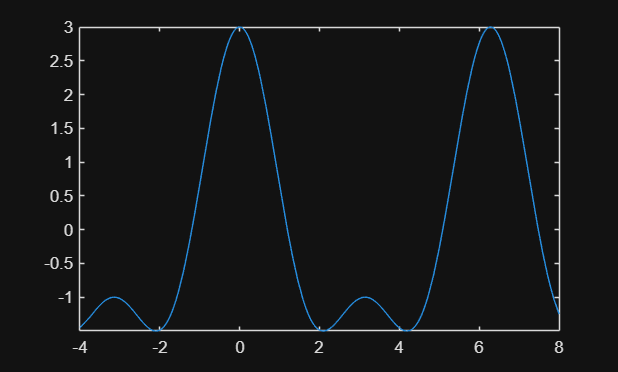

fplot(f, [M1, M2])

El primer paso es encontrar los valles en los que haya un mínimo. Para ello aplicamos el algoritmo de búsqueda de intervalos de los apuntes. Para este algoritmo necesitamos dos extremos, un punto entre ellos y un paso inicial. Vamos a definirlo para nuestro ejemplo aislado. 

x0 = 1; h = 0.1; 

Como para este algorirmo necesitamos la derivada vamos a estimarla: $f'(x) \approx \frac{f(x + \varepsilon) - f(x - \varepsilon)}{2\varepsilon}$ donde vamos a fijar $\varepsilon=10^{-5}$.

epsilon = 1e-5;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon);

Ahora inicializamos el algoritmo

f0 = f(x0);
g0 = df(x0);

Si la derivada es positiva buscamos hacia la izquierda

if g0 > 0
    h = -h;
end

Ahora aplicamos un bucle while. Lo que hace este bucle es crear un intervalo con el paso que le hemos dado. 

Si al crear el intervalo se sale de los límites nos da un aviso de que el mínimo puede estar en los extremos. 

Comprueba la función y su derivada en el punto nuevo del intervalo y si ha cambiado de signo la derivada, hemos encontrado un valle. Sino, aumenta el paso y sigue buscando. 

while true
    % Calcular nuevo punto
    x1 = x0 + h;
    
    % Verificar si nos salimos de las cotas M1 o M2
    if (h > 0 && x1 > M2) || (h < 0 && x1 < M1)
        a = []; b = []; 
        return; 
    end
    f1 = f(x1);
    g1 = df(x1);
    
    % Caso A: Buscando hacia la derecha (h > 0)
    if h > 0 && (g1 > 0 || f1 > f0)
        a = x0; 
        b = x1; 
        break; 
    end
    
    % Caso B: Buscando hacia la izquierda (h < 0)
    if h < 0 && (g1 < 0 || f1 > f0)
        a = x1; 
        b = x0; 
        break; 
    end
    
    % Si no se cumple lo anterior, expandimos la búsqueda.
    h = 2 * h;
    x0 = x1;
    f0 = f1;
    g0 = g1;
end

Ahora vemos que intervalo nos ha creado dadas nuestras condiciones iniciales

fprintf('El intervalo es: [%f, %f]\n', a, b);

El intervalo es: [1.700000, 2.500000]


Para ver que efectivamente encierra un mínimo, vamos a pintarlo

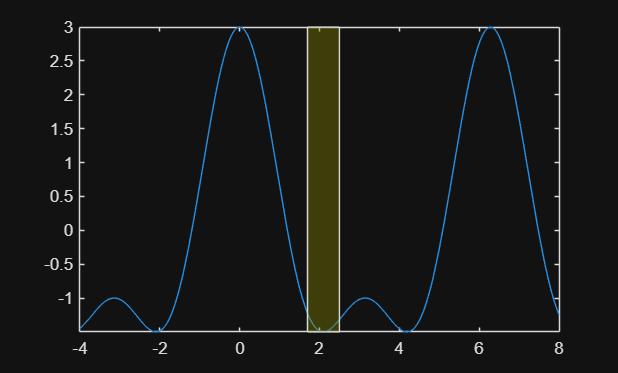

figure; 
h_plot = fplot(f, [M1, M2]);
yl = ylim; 
x_parche = [a, b, b, a];
y_parche = [yl(1), yl(1), yl(2), yl(2)];
h_shade = patch(x_parche, y_parche, [0.5 0.5 0], ...
               'FaceAlpha', 0.4);

Ahora que ya tendríamos el intervalo óptimo, aplicamos el algoritmo secanteprot para encontrar el mínimo en ese valle. Este algoritmo en una variante del de Newton en el que la segunda derivada se estima. Para esto necesitamos que los extremos del intervalo cumplan una de las siguientes condiciones: 

- 
$$f'(a)\lt0 \qquad f'(b)\gt0$$


- 
$$f'(a)\lt0 \qquad f(b)\gt f(a)$$


- 
$$f'(a)\gt0 \qquad f'(b)\gt0 \qquad f(b)\lt f(a)$$


Esto se cumple siempre que el intervalo lo hayamos sacado el intervalo de la busqueda anterior. 

El algoritmo se inicializa con un punto en el intervalo, una tolerancia y un número máximo de iteraciones. También iniciamos el contador de iteraciones. 

xk = (a + b)/2; tol = 1e-7; maxit = 50; k = 1; 

Los parámetros iniciales que necesitamos son: 

ga = df(a); gb = df(b); fa = f(a); fb = f(b); 

Para iniciar la estimación de la segunda derivada necesitamos un punto previo a `xk`. Con esta lógica que vemos a continuación nos aseguramos que este punto siempre caiga en el intervalo. para evitar errores. 

paso = (b - a) * 0.01;
if xk + paso <= b
    x_ant = xk + paso;
else
    x_ant = xk - paso;
end
g_ant = df(x_ant); fk = f(xk);

Para ver luego las evaluaciones que ha hecho, voy a crear una variable de historial

x_his = [a, b, xk]; fun = [fa, fb, fk]; 

Aplicamos ahora un bucle while que buscará el mínimo según la logica del algoritmo de Newton protegido.

while k <= maxit
    gk = df(xk);
    
    % Criterio de parada (Gradiente)
    if abs(gk) < tol
        break;
    end
    
    % Estimación de hk (Segunda Derivada)
    hk = (gk - g_ant) / (xk - x_ant);
    
    % Dirección de búsqueda (p) con Protección
    if hk > 0
        pk = -gk / hk; % Dirección tipo Newton
    else
        pk = -gk;      % Dirección tipo Descenso de Gradiente (protección)
    end
    
    % Cálculo de alfa (Saturación en límites a y b)
    if pk > 0
        alfa = min(1, (b - xk) / pk);
    elseif pk < 0
        alfa = min(1, (a - xk) / pk);
    else
        alfa = 0;
    end
    
    % Búsqueda de Línea
    % Asegura que el siguiente paso f(xk + alfa*pk) sea menor
    while f(xk + alfa * pk) >= fk && alfa > 1e-10
        alfa = alfa / 2;
    end
    
    % Actualización de variables
    x_ant = xk;  
    g_ant = gk;   
    
    xk = xk + alfa * pk;
    fk = f(xk);
    
    x_his = [x_his, xk];
    fun = [fun, fk];
    
    % Control de iteraciones
    if k == maxit
        disp('Máximo de iteraciones alcanzado.');
        break;
    end
    k = k + 1;
end
x_min = xk;
f_min = fk;

Ahora podemos ver el mínimo que ha encontrado

fprintf('El mínimo es: (%f, %f)\n', x_min, f_min);

El mínimo es: (2.094395, -1.500000)


Para verlo mejor vamos a pintarlo.

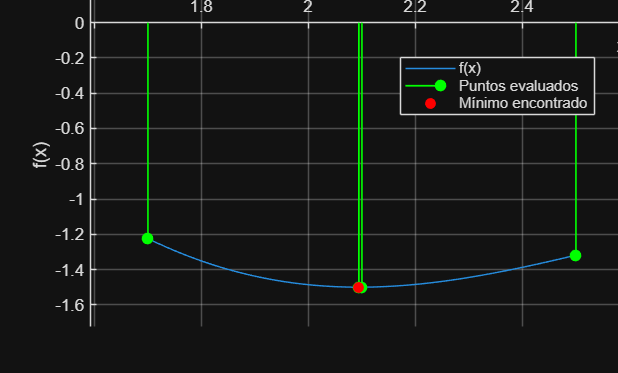

n_evals = length(x_his);
figure;
hold on;

h_func = fplot(f, [a, b]);
h_stems = stem(x_his, fun, 'filled', 'Color', 'g', ...
               'BaseValue', 0, 'LineWidth', 1);
h_min = plot(x_min, f_min, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');

y_data = get(h_func, 'YData');
y_max = max([y_data, fun, 0]); 
y_min = min([y_data, fun, 0]);
padding = (y_max - y_min) * 0.15;

ylim([y_min - padding, y_max + padding]);


grid on;
ax = gca;
ax.XAxisLocation = 'origin'; 
xlabel('x');
ylabel('f(x)');
title(sprintf('Optimización: %d Evaluaciones Realizadas', n_evals));
legend([h_func, h_stems, h_min], {'f(x)', 'Puntos evaluados', 'Mínimo encontrado'}, ...
       'Location', 'best');
hold off;

Nuestro algoritmo funciona. 

Para encontrar los máximos se repetiría el proceso anterior con $g(x) = -f(x)$.

Para encontrar los puntos de inflexión, se haría lo mismo con $g(x) = f'(x)$

## Unificación: 

Como hemos dicho antes, este proceso previo se aplica a todos los puntos del mallado 

Aplicamos la función `escanear`, que nos va a mallar el intervalo y llamará a la funcion `buscar_intervalo_derivada` para encontrar los intervalos que tienen un minimo dentro. 

Primero definimos una variable de pasos `n_pasos`, que nos divide el intervalo. Crearemos un paso de búsqueda pequeño, `h_init,` para evitar saltarnos un mínimo.

Con un bucle que itera sobre los $n$ puntos se realiza el siguiente proceso: 

- Llamamos a la función `intervalo_derivada`, y si se detecta que $f'$ cambia de signo, devuelve un intervalo $[a, \ b]$

- Con $[a, \ b]$ se lanza la función `secanteprot`, que busca el punto exacto donde $f'(x) = 0$, usando la aproximación de la secante para la segunda derivada $f''(x_k) \approx \frac{f'(x_k)-f'(x_{k-1})}{x_k-x_{k-1}}$.

- Filtramos los duplicados ya que varios puntos de la rejilla, dependiendo del paso en el mallado y la complejidad de la función pueden haber caido en el mismo intervalo y dar el mismo mínimo. Lo que hacemos es verificar que no lo tenemos ya en la lista de mínimos y si ya estaba lo ignoramos. 

Uno puede darse cuenta súper rápido que esto es un poco ineficiente, ya que por ejemplo si nuestra función fuera $f(x) = x^3-2x^2-x+2$, es una tontería mallar el intervalo inicial que nos den en 50 puntos. Pero si nuestra función fuera $f(x) = x\sin{x}$ ya no sería tanta tonteria si el intervalo es próximo al origen. 

Esto depende de nuestra función, en este caso voy a priorizar la exactitud por encima de la eficiencia computacional ya que las funciones que tenemos tampoco son excesivamente complejas. Pero no es de más recordar que cada punto del mallado es una iteración sobre todo el proceso. 

Dicho esto, comenzamos el proceso con la configuración inicial

Configuración inicial

f = @(x) 2*cos(x) + cos(2*x);
M1 = -4; M2 = 8;
n_pasos = 50; 
epsilon = 1e-5;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 

Ejecución del escaner 

res_f = escanear(f, M1, M2, n_pasos); % máximos y mínimos
res_df = escanear(df, M1, M2, n_pasos); % inflexiones

Con todo esto podemos concluir: 


--- RESUMEN DE PUNTOS ENCONTRADOS ---
        X           f_x          Tipo           Detalle   
    __________    _______    _____________    ____________

       -3.7094    -1.2646    {'Inflexión'}    {'-'       }
       -3.1416         -1    {'Máximo'   }    {'Relativo'}
       -2.5738    -1.2646    {'Inflexión'}    {'-'       }
       -2.0944       -1.5    {'Mínimo'   }    {'Relativo'}
      -0.93593    0.88961    {'Inflexión'}    {'-'       }
    4.1739e-13          3    {'Máximo'   }    {'Relativo'}
       0.93593    0.88961    {'Inflexión'}    {'-'       }
        2.0944       -1.5    {'Mínimo'   }    {'Relativo'}
        2.5738    -1.2646    {'Inflexión'}    {'-'       }
        3.1416         -1    {'Máximo'   }    {'Relativo'}
        3.7094    -1.2646    {'Inflexión'}    {'-'       }
        4.1888       -1.5    {'Mínimo'   }    {'Relativo'

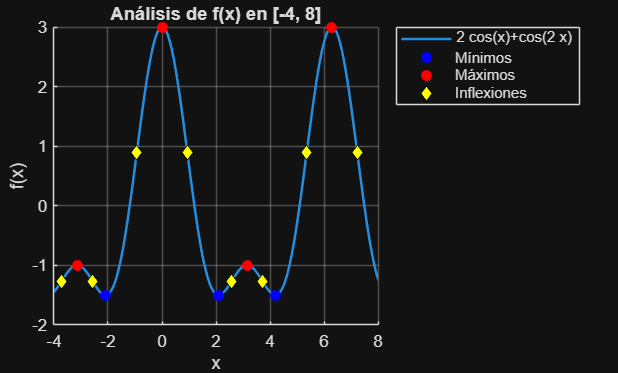

reporte_pintar(res_f, res_df, f, M1, M2)

## Aplicacion a otras funciones:

Aunque la práctica solo pide para 2 funciones voy a hacerlo para todas, porque, ¿por qué no?

Voy a utilizar en todas las funciones un mallado de 50 puntos y $\varepsilon = 10^{-5}$ para el cálculo de la primera derivada. Los voy a fijar de antemano.

n_pasos = 50; epsilon = 1e-5;

### Función P2:

$f(x) = \sin(x) + \sin\left(\frac{10}{3}x\right) $ en el dominio $[0, \ 15]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x            Tipo           Detalle   
    _______    __________    _____________    ____________

    0.54888        1.4884    {'Máximo'   }    {'Relativo'}
    0.96469        0.7479    {'Inflexión'}    {'-'       }
     1.3983     -0.013521    {'Mínimo'   }    {'Relativo'}
      1.859       0.87246    {'Inflexión'}    {'-'       }
     2.2961        1.7283    {'Máximo'   }    {'Relativo'}
     2.8356       0.27416    {'Inflexión'}    {'-'       }
     3.3873       -1.1999    {'Mínimo'   }    {'Relativo'}
     3.7861      -0.54676    {'Inflexión'}    {'-'       }
     4.1966       0.11909    {'Máximo'   }    {'Relativo'}
     4.6854      -0.90967    {'Inflexión'}    {'-'       }
     5.1457       -1.8996    {'Mínimo'   }    {'Relativo'}
     5.6704      -0.52338    {'Inflexión'}    {'-'       

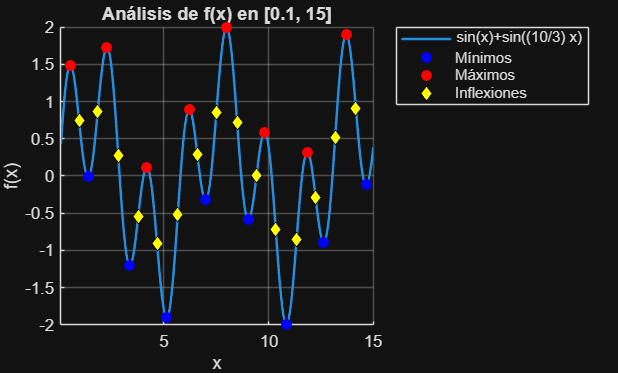

f = @(x) sin(x) + sin((10/3)*x);  M1 = 0.1; M2 = 15;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P3-k5-seno:

$f(x) = -\sum_{k=1}^{5} k \sin[(k+1)x + k]$ en el dominio $[-10, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x           Tipo           Detalle   
    ________    ________    _____________    ____________

     -9.7751     0.24325    {'Inflexión'}    {'-'       }
     -9.5358       3.082    {'Máximo'   }    {'Relativo'}
     -9.2792    -0.39354    {'Inflexión'}    {'-'       }
     -9.0374     -3.7325    {'Mínimo'   }    {'Relativo'}
      -8.781     0.33239    {'Inflexión'}    {'-'       }
     -8.5498      4.1234    {'Máximo'   }    {'Relativo'}
     -8.2598     -3.0088    {'Inflexión'}    {'-'       }
     -8.0087     -9.4947    {'Mínimo'   }    {'Relativo'}
     -7.6897      3.0128    {'Inflexión'}    {'-'       }
     -7.3973      14.838    {'Máximo'   }    {'Relativo'}
     -7.0926      1.5879    {'Inflexión'}    {'-'       }
     -6.7746     -12.031    {'Mínimo'   }    {'Relativo'}
     -6.5084

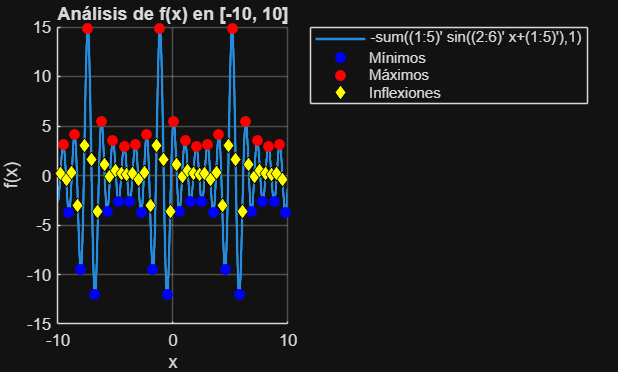

f = @(x) -sum((1:5)' .* sin((2:6)' * x + (1:5)'), 1);  M1 = -10; M2 = 10;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P3-k6-seno:

$f(x) = -\sum_{k=1}^{6} k \sin[(k+1)x + k]$ en el dominio $[-10, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
        X           f_x           Tipo           Detalle   
    _________    _________    _____________    ____________

      -9.8643    -0.019381    {'Inflexión'}    {'-'       }
       -9.654      -3.4404    {'Mínimo'   }    {'Relativo'}
      -9.4387      0.26601    {'Inflexión'}    {'-'       }
       -9.233       3.8605    {'Máximo'   }    {'Relativo'}
      -9.0101     -0.68417    {'Inflexión'}    {'-'       }
      -8.8022      -5.0225    {'Mínimo'   }    {'Relativo'}
      -8.5794      0.41862    {'Inflexión'}    {'-'       }
      -8.3798       5.4709    {'Máximo'   }    {'Relativo'}
      -8.1289      -4.1201    {'Inflexión'}    {'-'       }
       -7.913      -12.809    {'Mínimo'   }    {'Relativo'}
      -7.6356        4.466    {'Inflexión'}    {'-'       }
      -7.3824       20.754    {'Máximo'   } 

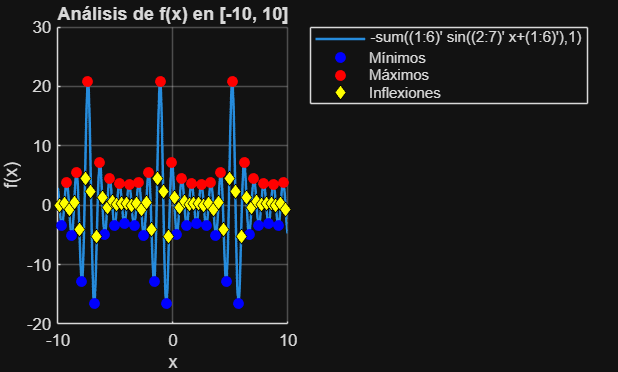

f = @(x) -sum((1:6)' .* sin((2:7)' * x + (1:6)'), 1);  M1 = -10; M2 = 10;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P5:

$f(x) = (3x - 1.4)\sin(18x)$ en el dominio $[-1.5, \ 1.5]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
        X           f_x           Tipo           Detalle   
    _________    _________    _____________    ____________

      -1.4851        5.853    {'Máximo'   }    {'ABSOLUTO'}
      -1.3996      0.33276    {'Inflexión'}    {'-'       }
      -1.3107      -5.3296    {'Mínimo'   }    {'ABSOLUTO'}
      -1.2254     -0.33262    {'Inflexión'}    {'-'       }
      -1.1364       4.8063    {'Máximo'   }    {'Relativo'}
      -1.0513      0.33244    {'Inflexión'}    {'-'       }
     -0.96209       -4.283    {'Mínimo'   }    {'Relativo'}
     -0.87725      -0.3322    {'Inflexión'}    {'-'       }
     -0.78786       3.7599    {'Máximo'   }    {'Relativo'}
     -0.70339      0.33184    {'Inflexión'}    {'-'       }
     -0.61372      -3.2369    {'Mínimo'   }    {'Relativo'}
     -0.52977     -0.33128    {'Inflexión'} 

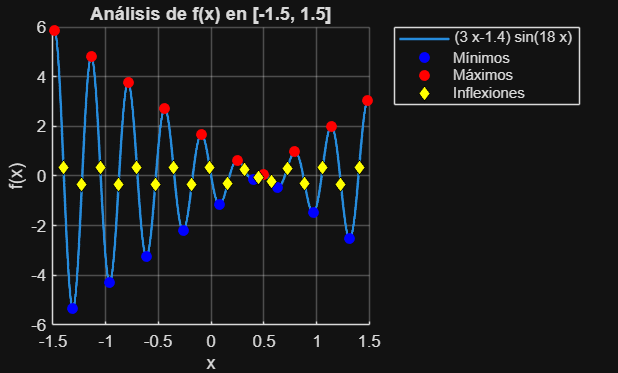

f = @(x) (3*x - 1.4).*sin(18*x);  M1 = -1.5; M2 = 1.5;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P7

$f(x) = \sin(x) + \sin\left(\frac{10}{3}x\right) + \ln(x) - 0.84x + 3$ en el dominio $[0.1, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X         f_x           Tipo           Detalle   
    _______    ________    _____________    ____________

    0.62006      3.4618    {'Máximo'   }    {'Relativo'}
    0.99272      2.8296    {'Inflexión'}    {'-'       }
     1.4112      2.1464    {'Mínimo'   }    {'Relativo'}
     1.8511      2.9091    {'Inflexión'}    {'-'       }
     2.2615      3.6378    {'Máximo'   }    {'ABSOLUTO'}
     2.8388      1.9189    {'Inflexión'}    {'-'       }
     3.4392      0.1608    {'Mínimo'   }    {'Relativo'}
     3.7842     0.60046    {'Inflexión'}    {'-'       }
     4.1361      1.0463    {'Máximo'   }    {'Relativo'}
     4.6866    -0.30583    {'Inflexión'}    {'-'       }
     5.1998     -1.6013    {'Mínimo'   }    {'Relativo'}
     5.6696    -0.55413    {'Inflexión'}    {'-'       }
     6.1544      0.5146   

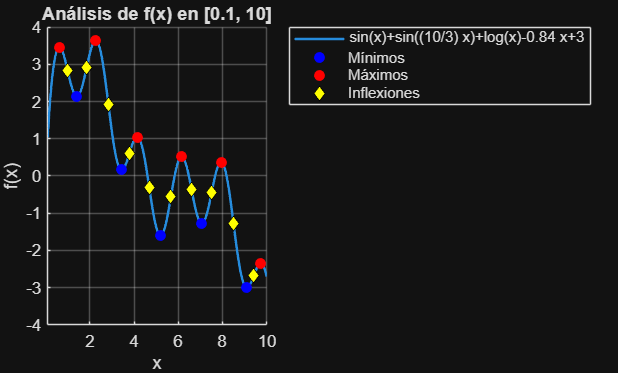

f = @(x) sin(x) + sin((10/3).*x) + log(x) - 0.84*x +3;  M1 = 0.1; M2 = 10;

df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P8-k5-coseno

$f(x) = -\sum_{k=1}^{5} k \cos[(k+1)x + k]
$ en el dominio $[-10, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X           f_x           Tipo           Detalle   
    ________    _________    _____________    ____________

     -9.7804       2.6396    {'Máximo'   }    {'Relativo'}
     -9.5277      -0.5358    {'Inflexión'}    {'-'       }
     -9.2863      -3.6137    {'Mínimo'   }    {'Relativo'}
     -9.0306     0.081643    {'Inflexión'}    {'-'       }
     -8.7941       3.5877    {'Máximo'   }    {'Relativo'}
     -8.5259      -1.5031    {'Inflexión'}    {'-'       }
     -8.2904      -6.1698    {'Mínimo'   }    {'Relativo'}
     -7.9804       3.7542    {'Inflexión'}    {'-'       }
     -7.7083       12.871    {'Máximo'   }    {'Relativo'}
     -7.3921      -0.9268    {'Inflexión'}    {'-'       }
     -7.0835      -14.508    {'Mínimo'   }    {'Relativo'}
     -6.7963      -3.3718    {'Inflexión'}    {'-'       

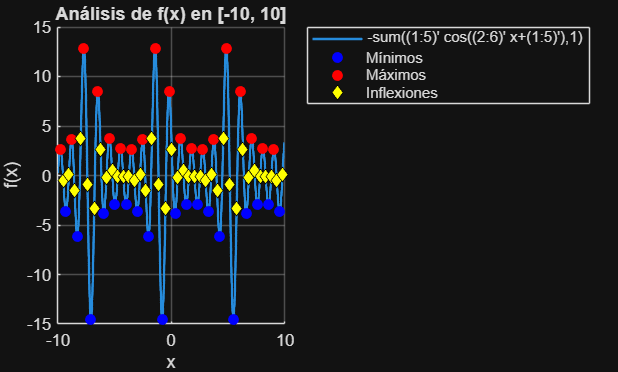

f = @(x) -sum((1:5)' .* cos((2:6)' * x + (1:5)'), 1); M1 = -10; M2 = 10; 
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P8-k6-coseno

$f(x) = -\sum_{k=1}^{6} k \cos[(k+1)x + k]
$ en el dominio $[-10, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
        X           f_x           Tipo           Detalle   
    _________    _________    _____________    ____________

      -9.8661      -3.6253    {'Mínimo'   }    {'Relativo'}
      -9.6516    -0.090898    {'Inflexión'}    {'-'       }
      -9.4443       3.3643    {'Máximo'   }    {'Relativo'}
      -9.2249     -0.72363    {'Inflexión'}    {'-'       }
      -9.0178      -4.6573    {'Mínimo'   }    {'Relativo'}
      -8.7952      0.25735    {'Inflexión'}    {'-'       }
       -8.591       4.8953    {'Máximo'   }    {'Relativo'}
      -8.3589      -1.9115    {'Inflexión'}    {'-'       }
      -8.1562      -8.1279    {'Mínimo'   }    {'Relativo'}
      -7.8873       5.4021    {'Inflexión'}    {'-'       }
      -7.6526       17.785    {'Máximo'   }    {'Relativo'}
      -7.3776      -1.3921    {'Inflexión'} 

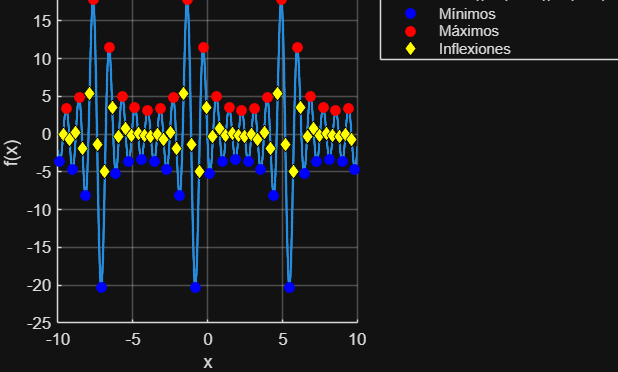

f = @(x) -sum((1:6)' .* cos((2:7)' * x + (1:6)'), 1); M1 = -10; M2 = 10; 
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P9

$f(x) = \sin(x) + \sin\left(\frac{2}{3}x\right)$ en el dominio $[0, \ 21]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
      X           f_x            Tipo           Detalle   
    ______    ___________    _____________    ____________

    1.8104          1.906    {'Máximo'   }    {'Relativo'}
    3.4743        0.40823    {'Inflexión'}    {'-'       }
    5.3622         -1.216    {'Mínimo'   }    {'Relativo'}
    6.7313       -0.54157    {'Inflexión'}    {'-'       }
    8.3961        0.22334    {'Máximo'   }    {'Relativo'}
    9.4248    -1.3101e-08    {'Inflexión'}    {'-'       }
    10.453       -0.22334    {'Mínimo'   }    {'Relativo'}
    12.118        0.54157    {'Inflexión'}    {'-'       }
    13.487          1.216    {'Máximo'   }    {'Relativo'}
    15.375       -0.40823    {'Inflexión'}    {'-'       }
    17.039         -1.906    {'Mínimo'   }    {'ABSOLUTO'}
     18.85    -1.4897e-06    {'Inflexión'}    {'-'       

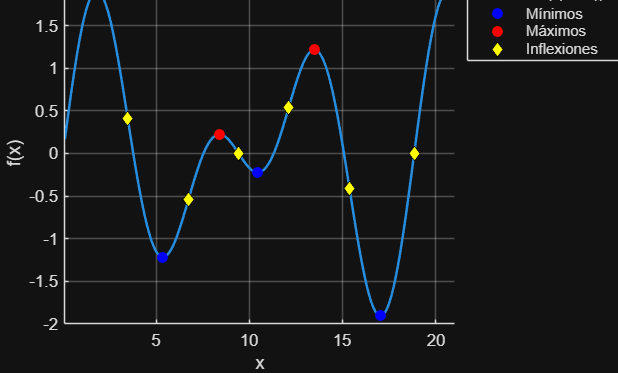

f = @(x) sin(x) + sin((2/3)*x);  M1 = 0.1; M2 = 21; 
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P10

$f(x) = -x\sin(x) $ en el dominio $[0, \ 15]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
      X         f_x           Tipo           Detalle   
    ______    ________    _____________    ____________

    1.0769    -0.94817    {'Inflexión'}    {'-'       }
    2.0288     -1.8197    {'Mínimo'   }    {'Relativo'}
    3.6436      1.7532    {'Inflexión'}    {'-'       }
    4.9132      4.8145    {'Máximo'   }    {'Relativo'}
    6.5783     -1.9135    {'Inflexión'}    {'-'       }
    7.9787     -7.9167    {'Mínimo'   }    {'Relativo'}
    9.6296      1.9582    {'Inflexión'}    {'-'       }
    11.086      11.041    {'Máximo'   }    {'ABSOLUTO'}
    12.722     -1.9757    {'Inflexión'}    {'-'       }
    14.207     -14.172    {'Mínimo'   }    {'ABSOLUTO'}



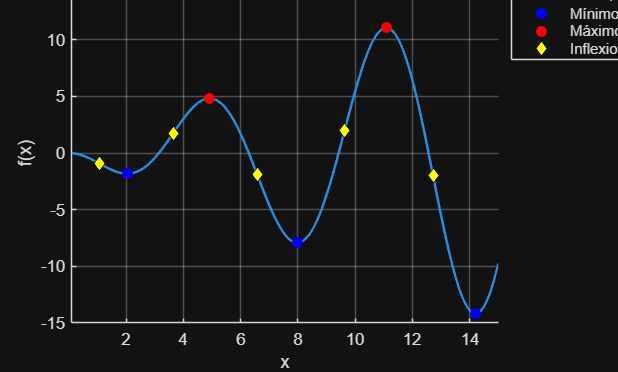

f = @(x) -x.*sin(x);  M1 = 0.1; M2 = 15;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P11 (La del ejemplo)

$f(x) = 2\cos(x) + \cos(2x)$ en el dominio $[-4, \ 8]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
        X           f_x          Tipo           Detalle   
    __________    _______    _____________    ____________

       -3.7094    -1.2646    {'Inflexión'}    {'-'       }
       -3.1416         -1    {'Máximo'   }    {'Relativo'}
       -2.5738    -1.2646    {'Inflexión'}    {'-'       }
       -2.0944       -1.5    {'Mínimo'   }    {'Relativo'}
      -0.93593    0.88961    {'Inflexión'}    {'-'       }
    4.1739e-13          3    {'Máximo'   }    {'Relativo'}
       0.93593    0.88961    {'Inflexión'}    {'-'       }
        2.0944       -1.5    {'Mínimo'   }    {'Relativo'}
        2.5738    -1.2646    {'Inflexión'}    {'-'       }
        3.1416         -1    {'Máximo'   }    {'Relativo'}
        3.7094    -1.2646    {'Inflexión'}    {'-'       }
        4.1888       -1.5    {'Mínimo'   }    {'Relativo'

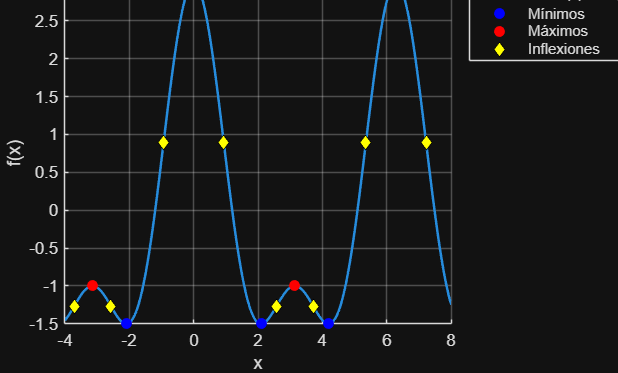

f = @(x) 2*cos(x) + cos(2*x);  M1 = -4; M2 = 8;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P12 

$f(x) = \sin^3(x) + \cos^3(x)$ en el dominio $[0, \ 7]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x            Tipo           Detalle   
    _______    __________    _____________    ____________

          0             1    {'Máximo'   }    {'Relativo'}
    0.36486       0.86066    {'Inflexión'}    {'-'       }
     0.7854       0.70711    {'Mínimo'   }    {'Relativo'}
     1.2059       0.86066    {'Inflexión'}    {'-'       }
     1.5708             1    {'Máximo'   }    {'Relativo'}
     2.3562    3.8192e-07    {'Inflexión'}    {'-'       }
     3.1416            -1    {'Mínimo'   }    {'Relativo'}
     3.5065      -0.86066    {'Inflexión'}    {'-'       }
      3.927      -0.70711    {'Máximo'   }    {'Relativo'}
     4.3475      -0.86066    {'Inflexión'}    {'-'       }
     4.7124            -1    {'Mínimo'   }    {'Relativo'}
     5.4978    1.5624e-07    {'Inflexión'}    {'-'       

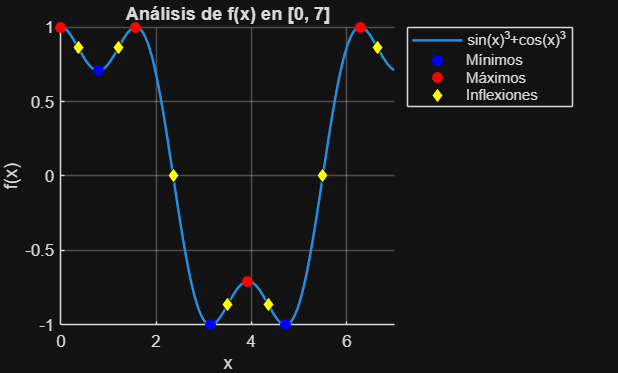

f = @(x) sin(x).^3 + cos(x).^3;  M1 = 0; M2 = 7;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P14 

$f(x) = -e^{-x} \sin(2\pi x)$ en el dominio $[0, \ 4]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x            Tipo           Detalle   
    _______    __________    _____________    ____________

    0.22488      -0.78869    {'Mínimo'   }    {'ABSOLUTO'}
    0.44976        -0.198    {'Inflexión'}    {'-'       }
    0.72488       0.47836    {'Máximo'   }    {'ABSOLUTO'}
    0.94976       0.12009    {'Inflexión'}    {'-'       }
     1.2249      -0.29014    {'Mínimo'   }    {'Relativo'}
     1.4498     -0.072839    {'Inflexión'}    {'-'       }
     1.7249       0.17598    {'Máximo'   }    {'Relativo'}
     1.9498      0.044179    {'Inflexión'}    {'-'       }
     2.2249      -0.10674    {'Mínimo'   }    {'Relativo'}
     2.4498     -0.026796    {'Inflexión'}    {'-'       }
     2.7249      0.064739    {'Máximo'   }    {'Relativo'}
     2.9498      0.016253    {'Inflexión'}    {'-'       

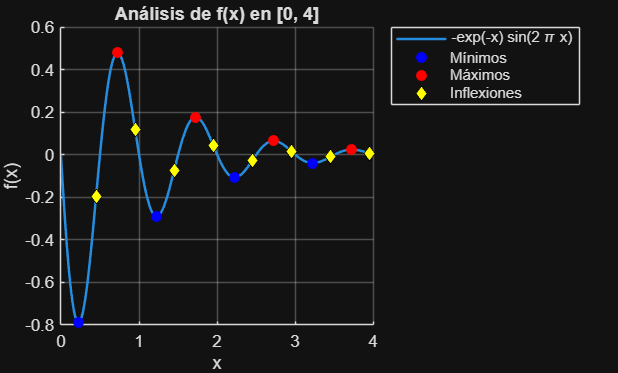

f = @(x) -exp(-x).*sin(2*pi*x);  M1 = 0; M2 = 4;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P21 

$f(x) = x \sin(x) + x \cos(2x)$ en el dominio $[-10, \ 10]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x           Tipo           Detalle   
    ________    ________    _____________    ____________

     -9.7087     -10.905    {'Mínimo'   }    {'ABSOLUTO'}
     -8.7928      2.5391    {'Inflexión'}    {'-'       }
     -7.9045      15.759    {'Máximo'   }    {'ABSOLUTO'}
     -7.0751      5.1277    {'Inflexión'}    {'-'       }
     -6.0788     -6.8118    {'Mínimo'   }    {'Relativo'}
     -5.4666     -3.6437    {'Inflexión'}    {'-'       }
     -4.7124           0    {'Máximo'   }    {'Relativo'}
     -4.1135     -1.8987    {'Inflexión'}    {'-'       }
     -3.4828     -3.8683    {'Mínimo'   }    {'Relativo'}
     -2.6685    -0.34434    {'Inflexión'}    {'-'       }
     -1.7873      3.3679    {'Máximo'   }    {'Relativo'}
     -1.1325      1.7499    {'Inflexión'}    {'-'       }
    -0.28088

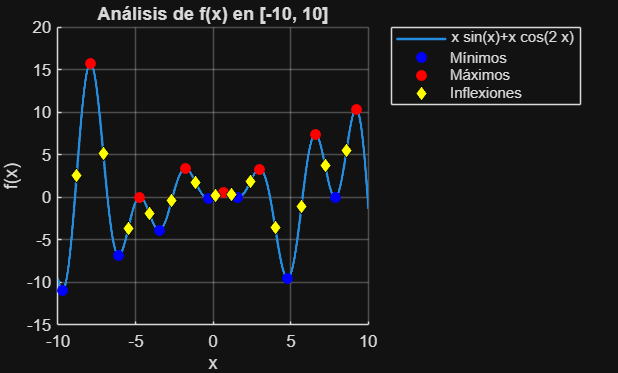

f = @(x) x.*sin(x) + x.*cos(2*x);  M1 = -10; M2 = 10; 
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función P22 

$f(x) = e^{-3x} - \sin^3(x)$ en el dominio $[0, \ 20]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X          f_x            Tipo           Detalle   
    _______    __________    _____________    ____________

    0.52278      0.083924    {'Inflexión'}    {'-'       }
    0.84712      -0.34207    {'Inflexión'}    {'-'       }
     1.5795      -0.99113    {'Mínimo'   }    {'Relativo'}
     2.1881      -0.54081    {'Inflexión'}    {'-'       }
     3.1415    8.0729e-05    {'Inflexión'}    {'-'       }
     4.0969       0.54434    {'Inflexión'}    {'-'       }
     4.7124             1    {'Máximo'   }    {'Relativo'}
     5.3279       0.54433    {'Inflexión'}    {'-'       }
     6.2832    6.5124e-09    {'Inflexión'}    {'-'       }
     7.2385      -0.54433    {'Inflexión'}    {'-'       }
      7.854            -1    {'Mínimo'   }    {'Relativo'}
     8.4695      -0.54433    {'Inflexión'}    {'-'       

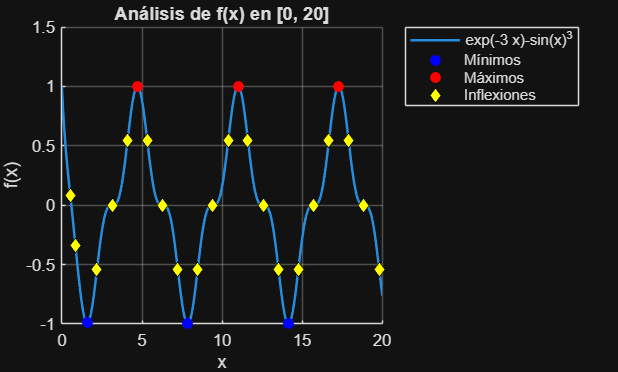

f = @(x) exp(-3*x) - sin(x).^3;  M1 = 0; M2 = 20;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función A1 

$f(x) = \sqrt{x} \sin(x) - x \cos(2x)$ en el dominio $[0, \ 14]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
      X          f_x           Tipo           Detalle   
    ______    _________    _____________    ____________

    0.2268    -0.096778    {'Mínimo'   }    {'Relativo'}
    1.0968       1.5716    {'Inflexión'}    {'-'       }
    1.7336       2.9418    {'Máximo'   }    {'Relativo'}
    2.6022     -0.40061    {'Inflexión'}    {'-'       }
    3.3536       -3.442    {'Mínimo'   }    {'Relativo'}
    4.0879     -0.34761    {'Inflexión'}    {'-'       }
     4.758       2.5592    {'Máximo'   }    {'Relativo'}
    5.5445       -2.103    {'Inflexión'}    {'-'       }
    6.2234       -6.328    {'Mínimo'   }    {'Relativo'}
    7.1086       2.5274    {'Inflexión'}    {'-'       }
    7.8882       10.677    {'Máximo'   }    {'ABSOLUTO'}
    8.7272      0.37218    {'Inflexión'}    {'-'       }
    9.5322      -9.6441   

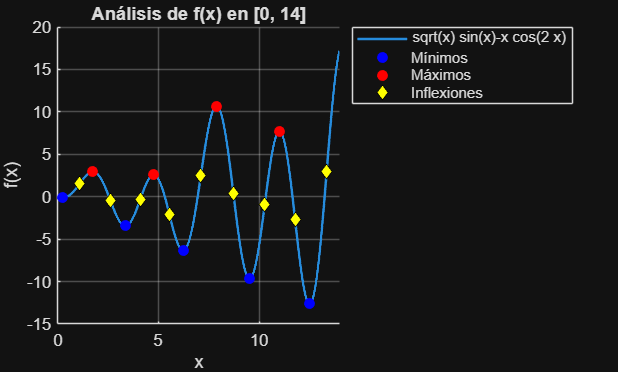

f = @(x) sqrt(x).*sin(x) - x.*cos(2*x);  M1 = 0; M2 = 14; 
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función A2 

$f(x) = \frac{1}{2}(x^2 - \cos(18x))$ en el dominio $[0, \ 10]$ (Voy a poner M2=2 porque sino la grafica es infumable)


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X           f_x           Tipo           Detalle   
    ________    _________    _____________    ____________

           0         -0.5    {'Mínimo'   }    {'ABSOLUTO'}
        0.02     -0.46775    {'Máximo'   }    {'Relativo'}
    0.087609    0.0069241    {'Inflexión'}    {'-'       }
     0.17562      0.51533    {'Máximo'   }    {'Relativo'}
     0.26146     0.037266    {'Inflexión'}    {'-'       }
     0.34692     -0.43945    {'Mínimo'   }    {'Relativo'}
     0.43668     0.098429    {'Inflexión'}    {'-'       }
     0.52685      0.63793    {'Máximo'   }    {'Relativo'}
     0.61052      0.18946    {'Inflexión'}    {'-'       }
     0.69384      -0.2578    {'Mínimo'   }    {'Relativo'}
     0.78574      0.31178    {'Inflexión'}    {'-'       }
     0.87809      0.88314    {'Máximo'   }    {'Relativo'

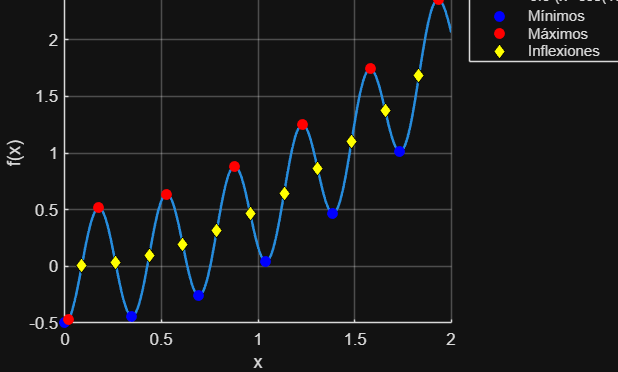

f = @(x) 0.5 * (x.^2 - cos(18*x));  M1 = 0; M2 = 2;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

### Función A3 

$f(x) = x^2 - 10\cos(2\pi x)$ en el dominio $[0, \ 5]$


--- RESUMEN DE PUNTOS ENCONTRADOS ---
       X         f_x          Tipo           Detalle   
    _______    _______    _____________    ____________

          0        -10    {'Mínimo'   }    {'ABSOLUTO'}
       0.05    -9.5081    {'Máximo'   }    {'Relativo'}
    0.25081    0.11356    {'Inflexión'}    {'-'       }
    0.50255     10.251    {'Máximo'   }    {'Relativo'}
    0.74919    0.61195    {'Inflexión'}    {'-'       }
    0.99496     -9.005    {'Mínimo'   }    {'Relativo'}
     1.2508     1.6152    {'Inflexión'}    {'-'       }
     1.5076     12.261    {'Máximo'   }    {'Relativo'}
     1.7492     3.1103    {'Inflexión'}    {'-'       }
     1.9899    -6.0202    {'Mínimo'   }    {'Relativo'}
     2.2508     5.1168    {'Inflexión'}    {'-'       }
     2.5127     16.282    {'Máximo'   }    {'Relativo'}
     2.7492     7.6087    {'Inflexión'} 

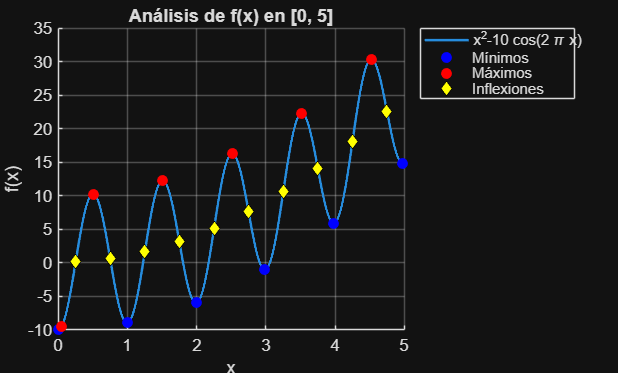

f = @(x) x.^2 - 10*cos(2*pi*x); M1 = 0; M2 = 5;
df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon); 
res_f = escanear(f, M1, M2, n_pasos); 
res_df = escanear(df, M1, M2, n_pasos); 
reporte_pintar(res_f, res_df, f, M1, M2);

## Anexo Funciones: 

function resultados = escanear(f, M1, M2, n_pasos)
    x_puntos = linspace(M1, M2, n_pasos);
    h_init = (M2 - M1) / (n_pasos * 2); 
    
    minimos = [];
    maximos = [];

    epsilon = 1e-5;
    df = @(x) (f(x + epsilon) - f(x - epsilon)) / (2 * epsilon);

    for i = 1:length(x_puntos)
        x0 = x_puntos(i);
        
        % Búsqueda de minimos
        [a, b] = buscar_intervalo_derivada(f, df, x0, M1, M2, h_init);
        if ~isempty(a) 
            [x_opt, f_opt] = secanteprot(a, b, (a+b)/2, 1e-7, 50, f, df);
            if ~isempty(x_opt) && x_opt >= M1 && x_opt <= M2
                % Evitar duplicados con una tolerancia
                if isempty(minimos) || all(abs(minimos(:,1) - x_opt) > 1e-3)
                    minimos = [minimos; x_opt, f_opt];
                end
            end
        end
                
        % Búsqueda de Máximos
        f_inv = @(x) -f(x);
        df_inv = @(x) -df(x); 
        [a_m, b_m] = buscar_intervalo_derivada(f_inv, df_inv, x0, M1, M2, h_init);
        if ~isempty(a_m) && ~isempty(b_m)
            [x_max, f_inv_max] = secanteprot(a_m, b_m, (a_m+b_m)/2, 1e-7, 50, f_inv, df_inv);
            
            if ~isempty(x_max)
                if isempty(maximos) || all(abs(maximos(:,1) - x_max) > 1e-3)
                    maximos = [maximos; x_max, -f_inv_max];
                end
            end
        end
    end
    
    if isempty(minimos), minimos = []; end
    if isempty(maximos), maximos = []; end
    
    resultados.minimos = sortrows(minimos);
    resultados.maximos = sortrows(maximos);
end

function [a, b] = buscar_intervalo_derivada(f, df, x0, M1, M2, h)
    f0 = f(x0);
    g0 = df(x0); 

    if g0 > 0, h = -h; end
    
    while true
        x1 = x0 + h;
        if (h > 0 && x1 > M2) || (h < 0 && x1 < M1)
            a = []; b = []; return; 
        end
        
        f1 = f(x1);
        g1 = df(x1);
      
        if (g0 * g1 <= 0) || (f1 > f0)
            a = min(x0, x1);
            b = max(x0, x1);
            return;
        end
        
        h = 2 * h;
        x0 = x1;
        f0 = f1;
        g0 = g1; 
    end
end

function [x_min, f_min] = secanteprot(a, b, xk, tol, maxit, f, df)

    paso = (b - a) * 0.01;
    if xk + paso <= b
        x_ant = xk + paso;
    else
        x_ant = xk - paso;
    end
    g_ant = df(x_ant);
    fk = f(xk);
    
    for k = 1:maxit
        gk = df(xk);
        
        if abs(gk) < tol
            break;
        end
        
        hk = (gk - g_ant) / (xk - x_ant);
        
        if hk > 1e-12
            pk = -gk / hk;
        else
            pk = -gk;
        end
        
        if pk > 0
            alfa = min(1, (b - xk) / pk);
        elseif pk < 0
            alfa = min(1, (a - xk) / pk);
        else
            alfa = 0;
        end
        
        while f(xk + alfa * pk) >= fk && alfa > 1e-10
            alfa = alfa / 2;
        end
        
        x_ant = xk;
        g_ant = gk;
        xk = xk + alfa * pk;
        fk = f(xk);
    end
    
    x_min = xk;
    f_min = fk;
end

function [] = reporte_pintar(res_f, res_df, f, M1, M2)
    % Imagen de las inflexiones
    x_inf = [];
    if ~isempty(res_df.minimos)
        x_inf = [x_inf; res_df.minimos(:,1)];
    end
    if ~isempty(res_df.maximos)
        x_inf = [x_inf; res_df.maximos(:,1)];
    end
    if ~isempty(x_inf)
        y_inf = arrayfun(f, x_inf);
        inflexiones = sortrows([x_inf, y_inf]);
    else
        inflexiones = [];
    end

    % Identificar Absolutos
    if ~isempty(res_f.minimos)
        f_min_all = res_f.minimos(:,2);
        min_abs_val = min(f_min_all);
    else
        min_abs_val = [];
    end
    if ~isempty(res_f.maximos)
        f_max_all = res_f.maximos(:,2);
        max_abs_val = max(f_max_all);
    else
        max_abs_val = [];
    end

    % Puntos
    total_pts = [];
    if ~isempty(res_f.minimos)
        total_pts = [total_pts; res_f.minimos, ones(size(res_f.minimos,1),1)];
    end
    if ~isempty(res_f.maximos)
        total_pts = [total_pts; res_f.maximos, 2*ones(size(res_f.maximos,1),1)];
    end
    if ~isempty(inflexiones)
        total_pts = [total_pts; inflexiones, 3*ones(size(inflexiones,1),1)];
    end
    total_pts = sortrows(total_pts, 1);

    % Limpieza numérica
    umbral = 1e-10;
    total_pts(abs(total_pts(:,2)) < umbral, 2) = 0;

    TipoStr = cell(size(total_pts,1), 1);
    NotaStr = cell(size(total_pts,1), 1);
    for j = 1:size(total_pts,1)
        y_val = total_pts(j,2);
        tipo  = total_pts(j,3);
        if tipo == 1
            TipoStr{j} = 'Mínimo';
            if ~isempty(min_abs_val) && abs(y_val - min_abs_val) < 1e-4
                NotaStr{j} = 'ABSOLUTO';
            else
                NotaStr{j} = 'Relativo';
            end
        elseif tipo == 2
            TipoStr{j} = 'Máximo';
            if ~isempty(max_abs_val) && abs(y_val - max_abs_val) < 1e-4
                NotaStr{j} = 'ABSOLUTO';
            else
                NotaStr{j} = 'Relativo';
            end
        else
            TipoStr{j} = 'Inflexión';
            NotaStr{j} = '-';
        end
    end

    % Tabla
    TablaRes = table(total_pts(:,1), total_pts(:,2), TipoStr, NotaStr, ...
                     'VariableNames', {'X', 'f_x', 'Tipo', 'Detalle'});
    fprintf('\n--- RESUMEN DE PUNTOS ENCONTRADOS ---\n');
    disp(TablaRes);

    % Pintar
    figure;
    hold on;
    fplot(f, [M1, M2], 'LineWidth', 1.5);
    if ~isempty(res_f.minimos)
        plot(res_f.minimos(:,1), res_f.minimos(:,2), 'bo', ...
             'MarkerFaceColor', 'b', 'MarkerSize', 6, 'DisplayName', 'Mínimos');
    end
    if ~isempty(res_f.maximos)
        plot(res_f.maximos(:,1), res_f.maximos(:,2), 'ro', ...
             'MarkerFaceColor', 'r', 'MarkerSize', 6, 'DisplayName', 'Máximos');
    end
    if ~isempty(inflexiones)
        plot(inflexiones(:,1), inflexiones(:,2), 'kd', ...
             'MarkerFaceColor', 'y', 'MarkerSize', 6, 'DisplayName', 'Inflexiones');
    end
    grid on;
    xlabel('x'); ylabel('f(x)');
    title(['Análisis de f(x) en [', num2str(M1), ', ', num2str(M2), ']']);
    legend('Location', 'northeastoutside');
    xlim([M1, M2]);
    hold off;
end